# Передача ссылки на функцию

## Ссылка на функцию

Если возникает задача, когда нужно над данными выполнять какую-то операцию, но операция эта может меняться от ситуации к ситуации, вместо того, чтобы писать каждый раз отдельную функцию, можно написать её один раз и просто передавать ссылку на функцию с нужной операцией.

Возьмём какой-то вектор:

x = [1, 2, 4, 6, 7, 8, 12, 12, 15];

И посчитаем минимальную, максимальную и среднюю разности между элементами вектора. Для этого будем нашей функции передавать ссылку на функцию с помощью символа "@".

y = myfun(x, @min)

y = 0

y = myfun(x, @max)

y = 4

y = myfun(x, @mean)

y = 1.7500

Передавать можно ссылки и на свои функции. Например, опишем фунцию поиска наиболее часто встречающегося элемента и передадим ссылку на неё.

y = myfun(x, @frequent)

y = 1

## Применение функций к совокупности данных

На практике может возникнуть ситуация, когда над каждым элементом матрицы или ячейки необходимо выполнить некоторую сложную операцию, невыражаемую через поэлементные операции. Рассмотрим это на следующем примере.

% Исходные данные
a = [1, 3, -2, 7, 0, 4, -5];
b = [5, 2, -1, 9];
c = [3, 0, 10];

% Задача: найти максимальный элемент каждого вектора

x = {a, b, c};          % Объединим удобства работы вектора в массив ячеек

% Обычное решение
for i = 1:length(x)
    y(i) = max(x{i});
end

% Правильное решение
z = cellfun(@max, x)

z =      7     9    10



isequal(z, y)           % Проверка на совпадение решений

ans = logical
   1


Функции `cellfun` был передан указатель на функцию и массив ячеек. Далее `cellfun` сама применила к каждому элементу массива ячеек `x` функцию `max` и объединила результаты в один массив. Рассмотрим другой пример.

% Исходные данные
x = [1:9];              % Задаём вектор с размерностями
x = reshape(x, 3, 3)    % Меняем размерность

x =      1     4     7
     2     5     8
     3     6     9



% Задача: сгенерировать квадратные матрицы с размерностями из x

% Обычное решение
a = cell(3, 3)

a = 3×3 cell array
    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}


for i = 1:3
    for j = 1:3
        a{i, j} = ones(x(i, j));
    end
end

% Правильное решение
b = arrayfun(@ones, x, 'UniformOutput', false);

isequal(a, b)

ans = logical
   1


Функция `arrayfun` работает аналогично, но применяется к массивам. Параметр `UniformOutput` определяет в каком виде должен быть представлен результат. Если он не указан, то считается по умолчанию равным `true` и тогда результаты выполнения переданной функции объединяются в массив, как это было в предыдущем примере. Однако в этом примере все сгенерированные матрицы будут иметь разную размерность, и поэтому не могут (и не должны) быть объединены в одну матрицу. Чтобы этого не происходило, необходимо задать параметру `UniformOutput` значение false, тогда результаты выполнения операции будут объединены в массив *ячеек*. Аналогично можно проводить обработку структур с помощью функции `structfun`.

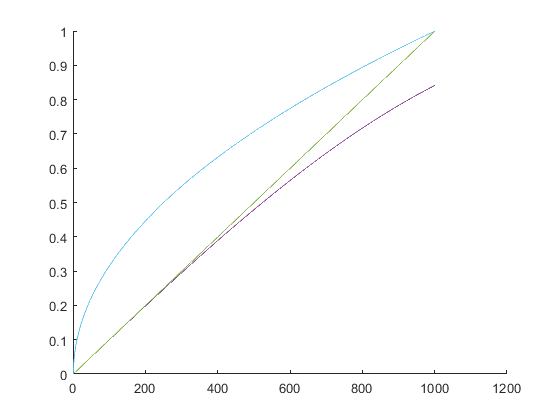

x = [0:0.001:1];
myfuns.fun1 = sin(x);
myfuns.fun2 = x;
myfuns.fun3 = sqrt(x);

figure;
hold on;
structfun(@plot, myfuns);

## Приложение

function y = frequent(x)
    x = sort(x);    % Сортируем
    y = [x(1), 1];  % Создаём матрицу для статистики
    
    k = 1;
    for i = 2:length(x)
        if (x(i) == y(k, 1))
            % Если такой элемент уже есть в таблице
            y(k, 2) = y(k, 2) + 1;
        else
            % Если такого элемента в таблице нет
            k = k + 1;
            y(k, :) = [x(i), 1];            
        end
    end
    [~, i] = max(y(:, 2));  % Ищем максимум по количеству вхождений
    y = y(i, 1);
end

function [y] = myfun(x, fun)
    x = diff(x);
    y = fun(x);    
end